#### Nombre: Camilo Hoyos, Ángel López

Fecha : 01/03/2023

# Taller 1 - Análisis numérico y computación científica

## Solución taller

### 1). 

#### a

-> Usando bisección:

f = @(x) exp(x) - 4 + x;

% Definimos los parámetros de entrada
xi = 0; % Límite inferior del intervalo
xu = 2; % Límite superior del intervalo
e = 1e-4; % Tolerancia deseada

% Llamamos a la función biseccion para obtener la raíz y los resultados
r = biseccion(f, xi, xu, e);

% Imprimimos la matriz de resultados como una tabla
tabla = array2table(r, 'VariableNames', {'xr', 'error'});
disp(tabla);

      xr        error   
    ______    __________

         1             1
       1.5           0.5
      1.25       0.33333
     1.125           0.2
    1.0625       0.11111
    1.0938      0.055556
    1.0781      0.028571
    1.0703      0.014493
    1.0742     0.0072464
    1.0723     0.0036364
    1.0732     0.0018182
    1.0737    0.00090909
    1.0735    0.00045475
    1.0736    0.00022738
    1.0737    0.00011369
    1.0737    5.6844e-05



-> Usando falsa posición:

f = @(x) exp(x) - 4 + x;
a = 0;
b = 2;
tol = 1e-4;
maxiter = 100;

[x, fx, iter] = falsa_posicion(f, a, b, tol, maxiter);

    Iteracion      xr          f(xr)         Error   
    _________    _______    ___________    __________

        1        0.71522        -1.2402        1.7964
        2        0.95557       -0.44429       0.25153
        3         1.0351       -0.14946      0.076849
        4         1.0612       -0.04915      0.024537
        5         1.0696      -0.016041     0.0079328
        6         1.0724      -0.005222     0.0025746
        7         1.0733     -0.0016986    0.00083665
        8         1.0736    -0.00055238    0.00027199
        9         1.0737    -0.00017962    8.8432e-05



-> Usando punto fijo:

% Función g(x) equivalente a f(x) = x.
g = @(x) exp(x) + x - 1;

% Aproximación inicial
p0 = 2;

% Tolerancia y número máximo de iteraciones
tol = 1e-4;
maxiter = 100;

% Ejecutar método de punto fijo
[p, iter] = punto_fijo(g, p0, tol, maxiter);

    Iteracion      p       Error 
    _________    ______    ______

        1        8.3891    6.3891
        2        4406.1    4397.7
        3           Inf       Inf
        4           Inf       NaN



-> Usando Newton - Raphson:

f = @(x) exp(x) - 4 + x;
df = @(x) exp(x) + 1;
p0 = 0.5;
tol = 1e-4;
maxiter = 15;
[p, iter, tabla] = newton_raphson(f, df, p0, tol, maxiter);
disp(tabla);

         0    0.5000       NaN
    1.0000    1.1989    0.6989
    2.0000    1.0795    0.1194
    3.0000    1.0737    0.0058
    4.0000    1.0737    0.0000



-> Usando secante:

f = @(x) exp(x) - 4 + x;
p0 = 0;
p1 = 2;
tol = 1e-4;
maxiter = 50;

[p, iter, tabla] = secante(f, p0, p1, tol, maxiter);

disp('Tabla de resultados:');

Tabla de resultados:


disp('iteración    p         error');

iteración    p         error


disp(tabla(1:iter+1,:));

         0         0       NaN
    1.0000    0.7152    1.2848
    2.0000    0.9556    0.2403
    3.0000    1.0897    0.1342
    4.0000    1.0730    0.0167
    5.0000    1.0737    0.0007
    6.0000    1.0737    0.0000



#### b

-> Usando bisección:

f = @(x) x - 0.2*sin(x) - 0.5;

% Definimos los parámetros de entrada
xi = 0; % Límite inferior del intervalo
xu = 1; % Límite superior del intervalo
e = 1e-4; % Tolerancia deseada

% Llamamos a la función biseccion para obtener la raíz y los resultados
r = biseccion(f, xi, xu, e);

% Imprimimos la matriz de resultados como una tabla
tabla = array2table(r, 'VariableNames', {'xr', 'error'});
disp(tabla);

      xr         error   
    _______    __________

        0.5             1
       0.75           0.5
      0.625       0.33333
     0.5625           0.2
    0.59375           0.1
    0.60938          0.05
    0.61719         0.025
    0.61328      0.012658
    0.61523     0.0063291
    0.61621     0.0031646
    0.61572     0.0015848
    0.61548    0.00079302
    0.61536    0.00039667
    0.61542    0.00019833
    0.61545    9.9167e-05



-> Usando falsa posición:

f = @(x) x - 0.2*sin(x) - 0.5;
a = 0;
b = 1;
tol = 1e-4;
maxiter = 100;

[x, fx, iter] = falsa_posicion(f, a, b, tol, maxiter);

    Iteracion      xr          f(xr)         Error   
    _________    _______    ___________    __________

        1        0.60117      -0.011948       0.66341
        2        0.61504    -0.00035787      0.022545
        3        0.61546    -1.0754e-05     0.0006741
        4        0.61547    -3.2316e-07    2.0255e-05



-> Usando punto fijo:

% Función g(x) equivalente a f(x) = x.
g = @(x) x - 0.2*sin(x) - 0.5;

% Aproximación inicial
p0 = 1;

% Tolerancia y número máximo de iteraciones
tol = 1e-4;
maxiter = 20;

% Ejecutar método de punto fijo
[p, iter] = punto_fijo(g, p0, tol, maxiter);

    Iteracion       p         Error 
    _________    ________    _______

        1         0.33171    0.66829
        2        -0.23343    0.56513
        3        -0.68716    0.45374
        4         -1.0603    0.37313
        5         -1.3858     0.3255
        6         -1.6892    0.30341
        7         -1.9906     0.3014
        8          -2.308    0.31737
        9         -2.6599    0.35193
       10         -3.0672    0.40734
       11         -3.5524    0.48514
       12         -4.1323    0.57987
       13         -4.7995    0.66728
       14         -5.4988    0.69924
       15         -6.1401    0.64128
       16         -6.6686    0.52853
       17         -7.0934    0.42481
       18         -7.4485    0.35511
       19         -7.7647    0.31622
       20         -8.0655     0.3008



-> Usando Newton - Raphson:

f = @(x) x - 0.2*sin(x) - 0.5;
df = @(x) 1 - (cos(x)/5);
p0 = 0.5;
tol = 1e-4;
maxiter = 15;
[p, iter, tabla] = newton_raphson(f, df, p0, tol, maxiter);
disp(tabla);

         0    0.5000       NaN
    1.0000    0.6163    0.1163
    2.0000    0.6155    0.0008
    3.0000    0.6155    0.0000



-> Usando secante:

f = @(x) x - 0.2*sin(x) - 0.5;
p0 = 0;
p1 = 1;
tol = 1e-4;
maxiter = 50;

[p, iter, tabla] = secante(f, p0, p1, tol, maxiter);

disp('Tabla de resultados:');

Tabla de resultados:


disp('iteración    p         error');

iteración    p         error


disp(tabla(1:iter+1,:));

         0         0       NaN
    1.0000    0.6012    0.3988
    2.0000    0.6150    0.0139
    3.0000    0.6155    0.0004
    4.0000    0.6155    0.0000



### 2).

Remplazando los valores dados en la ecuación (, tenemos:

36

ans = 36

### 3).

% Definamos la función a evaluar
f = @(x) -2*x^6 -1.5*x^4 +10*x + 2;

% (a) iteración de punto fijo
%g = @(x) (2*x^6 +1.5 *x^4-2)/10
g =@(x)((1.5*x^4 +10*x +2)/2)^(1/6)

g = function_handle with value:
    @(x)((1.5*x^4+10*x+2)/2)^(1/6)



% Aproximación inicial
p0 = 1;

% Tolerancia y número máximo de iteraciones
tol = 1e-4;
maxiter = 20;

[p, iter, tabla] = punto_fijo(g, p0, tol, maxiter)

    Iteracion      p         Error   
    _________    ______    __________

        1        1.3747       0.37473
        2         1.481       0.10628
        3        1.5134      0.032353
        4        1.5234      0.010067
        5        1.5266     0.0031535
        6        1.5276    0.00098986
        7        1.5279     0.0003109
        8         1.528    9.7671e-05



p = 1.5280

iter = 8

tabla =     1.0000    1.3747    0.3747
    2.0000    1.4810    0.1063
    3.0000    1.5134    0.0324
    4.0000    1.5234    0.0101
    5.0000    1.5266    0.0032
    6.0000    1.5276    0.0010
    7.0000    1.5279    0.0003
    8.0000    1.5280    0.0001



%(b) método de Newton – Raphson iniciando en 𝑥𝑖 = 1

df = @(x) -12*x^5-6*x^3 +10;
p0 = 0.5;
tol = 1e-4;
maxiter = 15;
[p, iter, tabla] = newton_raphson(f, df, p0, tol, maxiter);
disp(tabla)

         0    0.5000       NaN
    1.0000   -0.2746    0.7746
    2.0000   -0.2001    0.0745
    3.0000   -0.1997    0.0004
    4.0000   -0.1997    0.0000




%(c) Emplee el método de la secante a partir de 𝑥𝑖−1 = 0 y 𝑥𝑖 = 1.

p0 = 0;
p1 = 1;
tol = 1e-4;
maxiter = 50;
[p, iter, tabla] = secante(f, p0, p1, tol, maxiter);
disp(tabla)

         0         0       NaN
    1.0000   -0.3077    1.3077
    2.0000   -0.1588    0.1489
    3.0000   -0.1995    0.0407
    4.0000   -0.1997    0.0002
    5.0000   -0.1997    0.0000




%(d) Podríamos tomar el método de la secante como el mejor método para esta
%función, dado que el calcular una derivada aunque sea de un polinimio siempre 
% un procesamiento extra que es costoso y sacar la función g requiere de
% probar varias antes de encontrar la que pueda disminuir el error.

### 4).

Implentando el polinomio interpolador de Lagrange junto con la gráfica correspondiente de los puntos y el polinomio, tenemos:

% Definir los puntos de interpolación
x = [1.6, 2, 2.5, 3.2, 4, 4.5];
y = [2, 8, 14, 15, 8, 2];

% Número de puntos
n = length(x);

% Valores de x para evaluar el polinomio
xeval = linspace(min(x), max(x), 100);

% Polinomio interpolador de Lagrange
L = zeros(n,length(xeval));
for j = 1:n
    lj = ones(1,length(xeval));
    fprintf('L_%d(x) = ', j);
    for i = 1:n
        if i ~= j
            lj = lj .* (xeval - x(i))/(x(j) - x(i));
            fprintf('(x - %.1f)/(%.1f - %.1f)', x(i), x(j), x(i));
            if i < n
                fprintf(' * ');
            end
        end
    end
    fprintf('\n\n');
    L(j,:) = lj;
end

L_1(x) = 

(x - 2.0)/(1.6 - 2.0)

 * 

(x - 2.5)/(1.6 - 2.5)

 * 

(x - 3.2)/(1.6 - 3.2)

 * 

(x - 4.0)/(1.6 - 4.0)

 * 

(x - 4.5)/(1.6 - 4.5)

L_2(x) = 

(x - 1.6)/(2.0 - 1.6)

 * 

(x - 2.5)/(2.0 - 2.5)

 * 

(x - 3.2)/(2.0 - 3.2)

 * 

(x - 4.0)/(2.0 - 4.0)

 * 

(x - 4.5)/(2.0 - 4.5)

L_3(x) = 

(x - 1.6)/(2.5 - 1.6)

 * 

(x - 2.0)/(2.5 - 2.0)

 * 

(x - 3.2)/(2.5 - 3.2)

 * 

(x - 4.0)/(2.5 - 4.0)

 * 

(x - 4.5)/(2.5 - 4.5)

L_4(x) = 

(x - 1.6)/(3.2 - 1.6)

 * 

(x - 2.0)/(3.2 - 2.0)

 * 

(x - 2.5)/(3.2 - 2.5)

 * 

(x - 4.0)/(3.2 - 4.0)

 * 

(x - 4.5)/(3.2 - 4.5)

L_5(x) = 

(x - 1.6)/(4.0 - 1.6)

 * 

(x - 2.0)/(4.0 - 2.0)

 * 

(x - 2.5)/(4.0 - 2.5)

 * 

(x - 3.2)/(4.0 - 3.2)

 * 

(x - 4.5)/(4.0 - 4.5)

L_6(x) = 

(x - 1.6)/(4.5 - 1.6)

 * 

(x - 2.0)/(4.5 - 2.0)

 * 

(x - 2.5)/(4.5 - 2.5)

 * 

(x - 3.2)/(4.5 - 3.2)

 * 

(x - 4.0)/(4.5 - 4.0)

 * 

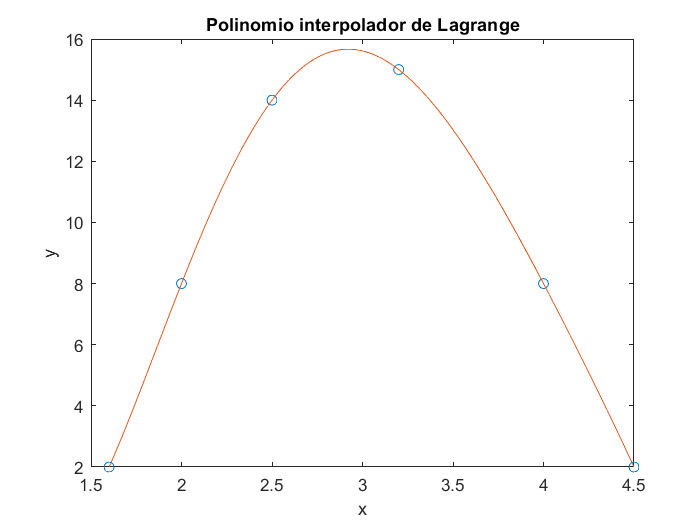

p = y * L;

% Visualización de los puntos y el polinomio interpolador
plot(x,y,'o',xeval,p)
xlabel('x')
ylabel('y')
title('Polinomio interpolador de Lagrange')


% Mostrar el polinomio interpolador
syms xx
f = 0;
fprintf('p(x) = ');

p(x) = 

for j = 1:n
    lj = 1;
    fprintf('( ');
    for i = 1:n
        if i ~= j
            lj = lj * (xx - x(i))/(x(j) - x(i));
            fprintf('(x - %.1f)/(%.1f - %.1f)', x(i), x(j), x(i));
            if i < n
                fprintf(' * ');
            end
        end
    end
    fprintf(' ) ');
    f = f + y(j) * lj;
    if j < n
        fprintf('+ ');
    end
end

( 

(x - 2.0)/(1.6 - 2.0)

 * 

(x - 2.5)/(1.6 - 2.5)

 * 

(x - 3.2)/(1.6 - 3.2)

 * 

(x - 4.0)/(1.6 - 4.0)

 * 

(x - 4.5)/(1.6 - 4.5)

 ) 

+ 

( 

(x - 1.6)/(2.0 - 1.6)

 * 

(x - 2.5)/(2.0 - 2.5)

 * 

(x - 3.2)/(2.0 - 3.2)

 * 

(x - 4.0)/(2.0 - 4.0)

 * 

(x - 4.5)/(2.0 - 4.5)

 ) 

+ 

( 

(x - 1.6)/(2.5 - 1.6)

 * 

(x - 2.0)/(2.5 - 2.0)

 * 

(x - 3.2)/(2.5 - 3.2)

 * 

(x - 4.0)/(2.5 - 4.0)

 * 

(x - 4.5)/(2.5 - 4.5)

 ) 

+ 

( 

(x - 1.6)/(3.2 - 1.6)

 * 

(x - 2.0)/(3.2 - 2.0)

 * 

(x - 2.5)/(3.2 - 2.5)

 * 

(x - 4.0)/(3.2 - 4.0)

 * 

(x - 4.5)/(3.2 - 4.5)

 ) 

+ 

( 

(x - 1.6)/(4.0 - 1.6)

 * 

(x - 2.0)/(4.0 - 2.0)

 * 

(x - 2.5)/(4.0 - 2.5)

 * 

(x - 3.2)/(4.0 - 3.2)

 * 

(x - 4.5)/(4.0 - 4.5)

 ) 

+ 

( 

(x - 1.6)/(4.5 - 1.6)

 * 

(x - 2.0)/(4.5 - 2.0)

 * 

(x - 2.5)/(4.5 - 2.5)

 * 

(x - 3.2)/(4.5 - 3.2)

 * 

(x - 4.0)/(4.5 - 4.0)

 * 

 ) 

fprintf('\n\n');
disp(['Polinomio interpolador: ' char(f)])

Polinomio interpolador: (3125*((5*xx)/8 - 1)*(xx - 2)*(xx - 4)*(xx - 5/2)*(xx - 9/2))/182 + (8*((5*xx)/2 - 4)*(xx - 4)*(xx - 5/2)*(xx - 9/2)*(xx - 16/5))/3 - (625*((5*xx)/2 - 5)*(xx - 4)*(xx - 5/2)*(xx - 9/2)*(xx - 16/5))/3132 - (20*((5*xx)/12 - 2/3)*(xx - 2)*(xx - 5/2)*(xx - 9/2)*(xx - 16/5))/3 - (40*((10*xx)/9 - 16/9)*(xx - 2)*(xx - 4)*(xx - 9/2)*(xx - 16/5))/3 + (8*((10*xx)/29 - 16/29)*(xx - 2)*(xx - 4)*(xx - 5/2)*(xx - 16/5))/13


### 5).

### 6).

% Definimos los datos
x = 1:10;
f = log(x);

% Valor a estimar
x_est = 5.5;

% Verificamos que el valor a estimar se encuentre dentro del rango de los datos
if x_est < min(x) || x_est > max(x)
    disp('Error: el valor a estimar está fuera del rango de los datos');
else
    % Encontramos el intervalo en el que se encuentra el valor a estimar
    i = find(x > x_est, 1);
    i = i - 1;

    % Definimos los puntos del intervalo y evaluamos la función en ellos
    x_int = x(i:i+3);
    f_int = f(i:i+3);

    % Calculamos los polinomios de Lagrange para cada punto en x_est
    n = length(x_int);
    L = zeros(1, n);
    for j = 1:n
        L(j) = Lagrange(x_int, j, x_est);
    end

    % Calculamos el valor estimado de f(x_est)
    f_est = sum(f_int .* L);

    % Mostramos el resultado en la consola
    disp(['El valor estimado de f(', num2str(x_est), ') es: ', num2str(f_est)]);
end

El valor estimado de f(5.5) es: 1.7046


### 7).

Graficando la función en el intervalo (-1,1): 

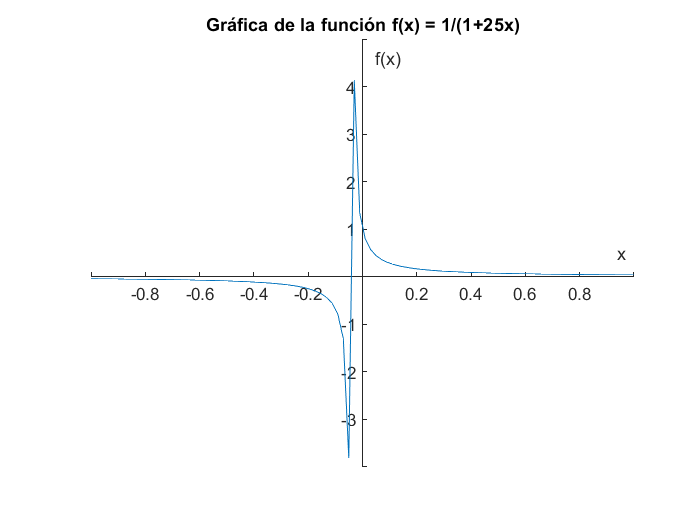

% Definimos el intervalo x
x = linspace(-1, 1);

% Evaluamos la función en el intervalo x
y = 1./(1 + 25*x);

% Graficamos la función
plot(x, y);
xlabel('x');
ylabel('f(x)');
title('Gráfica de la función f(x) = 1/(1+25x)');

% Mostramos los ejes de la gráfica
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
box(ax, 'off');

Obteniendo y graficando el polinomio de Langrange:


% Definimos los puntos equiespaciados x
x = [-1, -0.5, 0, 0.5, 1];

% Evaluamos la función en los puntos x
y = 1./(1 + 25*x);

% Definimos un vector de puntos donde evaluaremos el polinomio de Lagrange
x_interp = linspace(-1, 1);

% Calculamos el polinomio de Lagrange para cada punto en x_interp
n = length(x);
y_interp = zeros(size(x_interp));
for i = 1:length(x_interp)
    % Calculamos la suma de los polinomios de Lagrange evaluados en x_interp(i)
    % multiplicados por los valores correspondientes de y
    for j = 1:n
        L = Lagrange(x, j, x_interp(i));
        y_interp(i) = y_interp(i) + y(j) * L;
    end
end


% Graficamos la función y el polinomio de Lagrange
plot(x_interp, y_interp, 'LineWidth', 2);
hold on;
plot(x, y, 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlabel('x');
ylabel('f(x)');
title('Polinomio de Lagrange para la función f(x) = 1/(1+25x)');
legend('Polinomio de Lagrange', 'Puntos de interpolación');

% Definimos los puntos equiespaciados x
x = [-1, -0.5, 0, 0.5, 1];

% Evaluamos la función en los puntos x
y = 1./(1 + 25*x);

% Definimos un vector de puntos donde evaluaremos el polinomio de Lagrange
x_interp = linspace(-1, 1);



% Calculamos el polinomio de Lagrange para cada punto en x_interp
n = length(x);
y_interp = zeros(size(x_interp));
for i = 1:length(x_interp)
    % Calculamos la suma de los polinomios de Lagrange evaluados en x_interp(i)
    % multiplicados por los valores correspondientes de y
    for j = 1:n
        L = Lagrange(x, j, x_interp(i));
        y_interp(i) = y_interp(i) + y(j) * L;
    end
end

% Obtenemos el polinomio de Lagrange
syms z;
L_poly = 0;
for j = 1:n
    L_j = Lagrange(x, j, z);
    L_poly = L_poly + y(j) * L_j;
end

% Mostramos el polinomio de Lagrange en la consola
disp('Polinomio de Lagrange:');

Polinomio de Lagrange:


disp(L_poly);

$$\frac{8\,z\,\left(2\,z+2\right)\,\left(z-1\right)\,\left(z-\frac{1}{2}\right)}{69}-\frac{z\,\left(2\,z+1\right)\,\left(z-1\right)\,\left(z-\frac{1}{2}\right)}{72}+\frac{2\,z\,\left(\frac{z}{2}+\frac{1}{2}\right)\,\left(z-\frac{1}{2}\right)\,\left(z+\frac{1}{2}\right)}{39}-\frac{8\,z\,\left(\frac{2\,z}{3}+\frac{2}{3}\right)\,\left(z-1\right)\,\left(z+\frac{1}{2}\right)}{27}+4\,\left(z-1\right)\,\left(z+1\right)\,\left(z-\frac{1}{2}\right)\,\left(z+\frac{1}{2}\right)$$

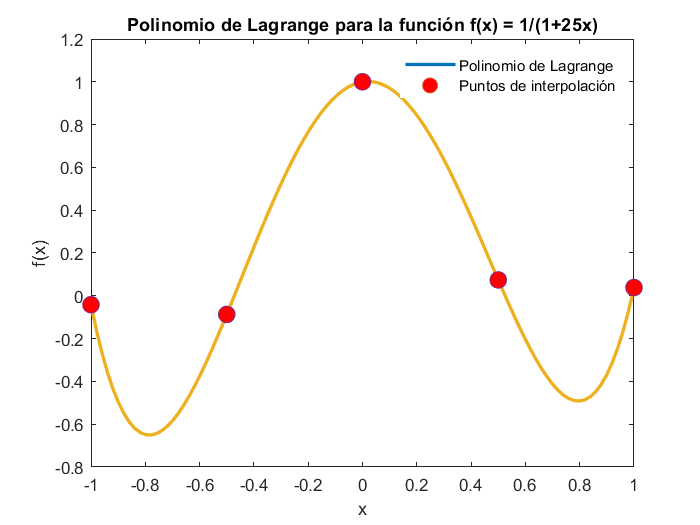



% Graficamos la función y el polinomio de Lagrange
plot(x_interp, y_interp, 'LineWidth', 2);
hold on;
plot(x, y, 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlabel('x');
ylabel('f(x)');
title('Polinomio de Lagrange para la función f(x) = 1/(1+25x)');
legend('Polinomio de Lagrange', 'Puntos de interpolación');

## Algoritmos utilizados:

% Definiendo las funciones 

% -----------------------------------------------------
function [r] = biseccion(f, xi, xu, e)
    a = xi;
    b = xu;
    xr = (a+b)/2;
    xr1 = 0;
    n = 0;
    
    % Inicializamos la matriz de resultados con el primer valor de xr
    r = [xr abs((b-a)/b)];
    
    while abs((b-a)/b) > e
        p = f(a)*f(xr);
        if p < 0
            b = xr;
        else
           a = xr;
        end
        xr1 = xr;
        xr = (a+b)/2;
        n = n + 1;
        r = [r; xr abs((b-a)/b)]; % Agregamos el nuevo valor de xr y el error a la matriz de resultados
    end
end

% -----------------------------------------------------

function [x, fx, iter] = falsa_posicion(f, a, b, tol, maxiter)
% f: función a evaluar
% a, b: intervalo inicial
% tol: tolerancia para el error relativo
% maxiter: número máximo de iteraciones permitidas
% x: raíz aproximada encontrada
% fx: valor de la función evaluada en la raíz aproximada encontrada
% iter: número de iteraciones realizadas

% Evaluamos la función en los extremos del intervalo
fa = f(a);
fb = f(b);

% Verificamos que haya cambio de signo en la función
if sign(fa) == sign(fb)
    error('La función debe cambiar de signo en el intervalo dado');
end

% Inicializamos variables
iter = 0;
error = tol + 1;
xr = b;

% Creamos una matriz para guardar los resultados de cada iteración
resultados = zeros(maxiter, 4);

% Iteramos hasta alcanzar la tolerancia o el número máximo de iteraciones
while error > tol && iter < maxiter
    % Calculamos la raíz aproximada
    xr_ant = xr;
    xr = a - (fa*(b-a))/(fb-fa);
    fxr = f(xr);
    iter = iter + 1;
    error = abs((xr - xr_ant)/xr);
    
    % Actualizamos el intervalo
    if sign(fxr) == sign(fa)
        a = xr;
        fa = fxr;
    else
        b = xr;
        fb = fxr;
    end
    
    % Guardamos los resultados de la iteración actual en la matriz
    resultados(iter, :) = [iter, xr, fxr, error];
end

% Asignamos el valor de la raíz aproximada encontrada
x = xr;
fx = fxr;

% Eliminamos las filas sobrantes en la matriz de resultados
resultados = resultados(1:iter, :);

% Mostramos los resultados por iteración en una tabla
tabla_resultados = array2table(resultados, 'VariableNames', {'Iteracion', 'xr', 'f(xr)', 'Error'});
disp(tabla_resultados);
end


% -----------------------------------------------------
%Punto fijo

% function [p, iter, tabla] = punto_fijo(g, p0, tol, maxiter)
% % Algoritmo de punto fijo
% % Entradas:
% %   g: Función de punto fijo.
% %   p0: Aproximación inicial.
% %   tol: Tolerancia de error.
% %   maxiter: Número máximo de iteraciones.
% % Salidas:
% %   p: Aproximación al punto fijo.
% %   iter: Número de iteraciones realizadas.
% %   tabla: Tabla que muestra los resultados por cada iteración.
% 
% iter = 0;
% tabla = zeros(maxiter, 3);
% tabla(iter+1, :) = [iter p0 NaN];
% 
% while iter < maxiter
%     p = g(p0);
%     if abs(p - p0) < tol
%         tabla(iter+1, :) = [iter+1 p abs(p - p0)];
%         return
%     end
%     iter = iter + 1;
%     tabla(iter+1, :) = [iter p abs(p - p0)];
%     p0 = p;
% end
% disp('El método de punto fijo no convergió.');
% resultado = 1;
% end

function [p, iter, tabla] = punto_fijo(g, p0, tol, maxiter)
% Método de punto fijo
% Entradas:
%   g: Función g(x) equivalente a f(x) = x.
%   p0: Aproximación inicial.
%   tol: Tolerancia de error.
%   maxiter: Número máximo de iteraciones.
% Salidas:
%   p: Aproximación a la solución.
%   iter: Número de iteraciones realizadas.
%   tabla: Tabla que muestra los resultados por cada iteración.

% Inicialización de variables
iter = 0;
p = p0;
err = inf;
tabla = NaN(maxiter, 3);


% Iteraciones del método de punto fijo
while (err > tol) && (iter < maxiter)
    p_anterior = p;
    p = g(p_anterior);
    err = abs(p - p_anterior);
    iter = iter + 1;
    tabla(iter, :) = [iter p err];
end

% Mostrar tabla
if iter > 0
    tabla = tabla(1:iter, :);
    disp(array2table(tabla(1:iter, :), 'VariableNames', {'Iteracion', 'p', 'Error'}))

else
    disp('El método de punto fijo no convergió.');
end

end



% -----------------------------------------------------
% Newton Raphson

% function [r] = new_rap(f,dfx,e,x0)
%     syms x
%     Ea = 1;
%     n=0;
% 
%     while Ea > e
%         fxn = x0-(f(x0)/dfx(x0));
%         Ea = abs((fxn-x0)/fxn);
%         x0=fxn;
%         n=n+1;
%         r(n,1)=x0;
%         r(n,2)=Ea;
%         if n>20
%             break
%         end
% 
%     end
% end

function [p, iter, tabla] = newton_raphson(f, df, p0, tol, maxiter)
% Método de Newton-Raphson
% Entradas:
%   f: Función a encontrar la raíz.
%   df: Derivada de la función.
%   p0: Aproximación inicial.
%   tol: Tolerancia de error.
%   maxiter: Número máximo de iteraciones.
% Salidas:
%   p: Aproximación a la raíz.
%   iter: Número de iteraciones realizadas.
%   tabla: Tabla que muestra los resultados por cada iteración.

iter = 0;
tabla = zeros(maxiter, 3);
tabla(iter+1, :) = [iter p0 NaN];

while iter < maxiter
    fp = f(p0);
    dfp = df(p0);
    p = p0 - fp/dfp;
    if abs(p - p0) < tol
        iter = iter + 1;
        tabla(iter+1, :) = [iter p abs(p - p0)];
        tabla = tabla(1:iter+1, :);
        return
    end
    iter = iter + 1;
    tabla(iter+1, :) = [iter p abs(p - p0)];
    p0 = p;
end
disp('El método de Newton-Raphson no convergió.');
end



% -----------------------------------------------------
% Secante

% function [r] = secante(f,e,x0,xi)
%     xrn = 0;
%     Ea = 1;
%     n=0;
%     fi= f(xi);
%     f0= f(x0);
% 
%     while Ea > e
%         xr = xi - ((fi*(x0-xi))/(f0-fi));
%         Ea= (xr-xrn)/xr;
%         xrn = xr;
%         n=n+1;
%         r(n,1)=xr;
%         r(n,2)=Ea;
%     end
% end
function [p, iter, tabla] = secante(f, p0, p1, tol, maxiter)
% Método de la secante
% Entradas:
%   f: Función a encontrar la raíz.
%   p0, p1: Aproximaciones iniciales.
%   tol: Tolerancia de error.
%   maxiter: Número máximo de iteraciones.
% Salidas:
%   p: Aproximación a la raíz.
%   iter: Número de iteraciones realizadas.
%   tabla: Tabla que muestra los resultados por cada iteración.

iter = 0;
tabla = zeros(maxiter, 3);
tabla(iter+1, :) = [iter p0 NaN];

while iter < maxiter
    fp0 = f(p0);
    fp1 = f(p1);
    p = p1 - fp1*(p1 - p0)/(fp1 - fp0);
    if abs(p - p1) < tol
        iter = iter + 1;
        tabla(iter+1, :) = [iter p abs(p - p1)];
        tabla = tabla(1:iter+1, :);
        return
    end
    iter = iter + 1;
    tabla(iter+1, :) = [iter p abs(p - p1)];
    p0 = p1;
    p1 = p;
end
disp('El método de la secante no convergió.');
end

% -----------------------------------------------------
% Splines cúbicos
% function [a, b, c, d] = spline_cubico(x, f)
% % Método de splines cúbicos
% % Entradas:
% %   x: Vector de nodos x1, x2, ..., xn.
% %   f: Vector de valores de la función f en los nodos.
% % Salidas:
% %   a, b, c, d: Coeficientes de los splines cúbicos.
% 
% n = length(x) - 1;
% h = diff(x);
% 
% % Paso 1: Resolver el sistema tridiagonal para encontrar los coeficientes c
% A = spdiags([h(1:n-1) 2*(h(1:n-1)+h(2:n)) h(2:n-1)], [-1 0 1], n-1, n-1);
% rhs = 3*diff([f(1); f; f(n)])'./(h');
% c = [0; A\rhs'; 0];
% 
% % Paso 2: Calcular los coeficientes a, b y d
% d = diff(c)./h';
% b = (diff(f)./h') - h'.*c(1:n-1)./3 - h'.*c(2:n)./6;
% a = f(1:n-1);
% 
% % Ajustar las dimensiones de los vectores de salida
% b = [b; NaN];
% c = [c; NaN];
% d = [d; NaN];
% end

% % Definimos la función para calcular los polinomios de Lagrange
% function L = Lagrange(x, j, z)
%     % Calcula el polinomio de Lagrange L_j(z) para el punto z y los puntos x
%     % en la posición j
%     n = length(x);
%     L = 1;
%     for i = 1:n
%         if i ~= j
%             L = L * (z - x(i)) / (x(j) - x(i));
%         end
%     end
% end
% Definimos la función para calcular los polinomios de Lagrange
function L = Lagrange(x, j, z)
    % Calcula el polinomio de Lagrange L_j(z) para el punto z y los puntos x
    % en la posición j
    n = length(x);
    L = 1;
    for i = 1:n
        if i ~= j
            L = L * (z - x(i)) / (x(j) - x(i));
        end
    end
end